clc
clear all

% 定义元胞数组
cellArray_Yale = {{82.66, 'SSC'}, {88.02, 'LRR'}, {91.34, 'LRSC'}, {81.72, 'NSC'},...
             {88.95, 'SMR'}, {85.41, 'KSSC'}, {82.73, 'LSR1'}, {93.74, 'KTRR'},...
                {94.30, 'BDR-B'}, {95.16, 'FLNNSC'}};
cellArray_USPS = {{84.52, 'SSC'}, {86.89, 'LRR'}, {77.10, 'LRSC'}, {84.74, 'NSC'},...
             {88.37, 'SMR'}, {82.26, 'KSSC'}, {82.54, 'LSR1'}, {84.96, 'KTRR'},...
                {89.29, 'BDR-B'}, {99.70, 'FLNNSC'}};
cellArray_COIL20 = {{73.92, 'SSC'}, {75.92, 'LRR'}, {68.05, 'LRSC'}, {71.83, 'NSC'},...
             {69.69, 'SMR'}, {77.36, 'KSSC'}, {67.62, 'LSR1'}, {84.38, 'KTRR'},...
                {78.13, 'BDR-B'}, {87.29, 'FLNNSC'}};
cellArray_ORL = {{67.00, 'SSC'}, {71.25, 'LRR'}, {72.75, 'LRSC'}, {77.50, 'NSC'},...
             {75.50, 'SMR'}, {74.75, 'KSSC'}, {76.50, 'LSR1'}, {80.00, 'KTRR'},...
                {80.25, 'BDR-B'}, {82.25, 'FLNNSC'}};

% 提取元胞数组中的数值数据
values_Yale = cellfun(@(x) x{1}, cellArray_Yale);
values_USPS = cellfun(@(x) x{1}, cellArray_USPS);
values_COIL20 = cellfun(@(x) x{1}, cellArray_COIL20);
values_ORL = cellfun(@(x) x{1}, cellArray_ORL);

% 对数值数据进行排序，并获取排序后的索引
[~, idx_Yale] = sort(values_Yale, 'ascend');
[~, idx_USPS] = sort(values_USPS, 'ascend');
[~, idx_COIL20] = sort(values_COIL20, 'ascend');
[~, idx_ORL] = sort(values_ORL, 'ascend');


% 将排序后的结果存入新的元胞数组中
sortedCellArray_Yale = cell(size(cellArray_Yale));
sortedCellArray_USPS = cell(size(cellArray_USPS));
sortedCellArray_COIL20 = cell(size(cellArray_COIL20));
sortedCellArray_ORL = cell(size(cellArray_ORL));
for i = 1:length(idx_Yale)
    sortedCellArray_Yale{i}{1} = cellArray_Yale{i}{1};
    sortedCellArray_Yale{i}{2} = cellArray_Yale{i}{2};
    sortedCellArray_Yale{i}{3} = find(idx_Yale == i);
end

for i = 1:length(idx_USPS)
    sortedCellArray_USPS{i}{1} = cellArray_USPS{i}{1};
    sortedCellArray_USPS{i}{2} = cellArray_USPS{i}{2};
    sortedCellArray_USPS{i}{3} = find(idx_USPS == i);
end

for i = 1:length(idx_COIL20)
    sortedCellArray_COIL20{i}{1} = cellArray_COIL20{i}{1};
    sortedCellArray_COIL20{i}{2} = cellArray_COIL20{i}{2};
    sortedCellArray_COIL20{i}{3} = find(idx_COIL20 == i);
end

for i = 1:length(idx_ORL)
    sortedCellArray_ORL{i}{1} = cellArray_ORL{i}{1};
    sortedCellArray_ORL{i}{2} = cellArray_ORL{i}{2};
    sortedCellArray_ORL{i}{3} = find(idx_ORL == i);
end

% 根据索引对元胞数组进行排序
% sortedCellArray_Yale = cellArray_Yale(idx_Yale);
% sortedCellArray_USPS = cellArray_USPS(idx_USPS);
% sortedCellArray_COIL20 = cellArray_COIL20(idx_COIL20);
% sortedCellArray_ORL = cellArray_ORL(idx_ORL);

% 显示排序后的结果
disp(sortedCellArray_Yale);

    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}



disp(sortedCellArray_USPS);

    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}



disp(sortedCellArray_COIL20);

    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}



disp(sortedCellArray_ORL);

    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}




% 4个数据集，10种方法构成矩阵
for i = 1:length({'Yale', 'USPS', 'COIL20', 'ORL'})
    for j = 1:length(cellArray_Yale)
        if i == 1
            accMatrix(i,j) = sortedCellArray_Yale{j}{3};
        elseif i == 2
            accMatrix(i,j) = sortedCellArray_USPS{j}{3};
        elseif i == 3
            accMatrix(i,j) = sortedCellArray_COIL20{j}{3};
        elseif i == 4
            accMatrix(i,j) = sortedCellArray_ORL{j}{3};
        end
    end
end
% 显示构造出的矩阵
disp(accMatrix);

     2     5     7     1     6     4     3     8     9    10
     4     7     1     5     8     2     3     6     9    10
     5     6     2     4     3     7     1     9     8    10
     1     2     3     7     5     4     6     8     9    10




avgAcc_matrix = mean(accMatrix);
disp(avgAcc_matrix);

    3.0000    5.0000    3.2500    4.2500    5.5000    4.2500    3.2500    7.7500    8.7500   10.0000



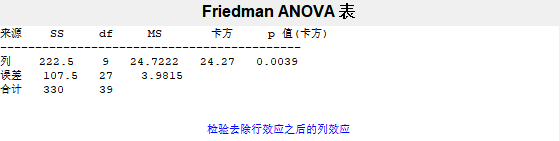


% Friedman测试
[p, table, stats] = friedman(accMatrix);


disp(p);

    0.0039



disp(table);

    {'来源'}    {'SS'      }    {'df'}    {'MS'      }    {'卡方'    }    {'p 值(卡方)'}
    {'列'  }    {[222.5000]}    {[ 9]}    {[ 24.7222]}    {[ 24.2727]}    {[   0.0039]}
    {'误差'}    {[107.5000]}    {[27]}    {[  3.9815]}    {0×0 double}    {0×0 double }
    {'合计'}    {[     330]}    {[39]}    {0×0 double}    {0×0 double}    {0×0 double }



disp(stats);

       source: 'friedman'
            n: 4
    meanranks: [3 5 3.2500 4.2500 5.5000 4.2500 3.2500 7.7500 8.7500 10]
        sigma: 3.0277



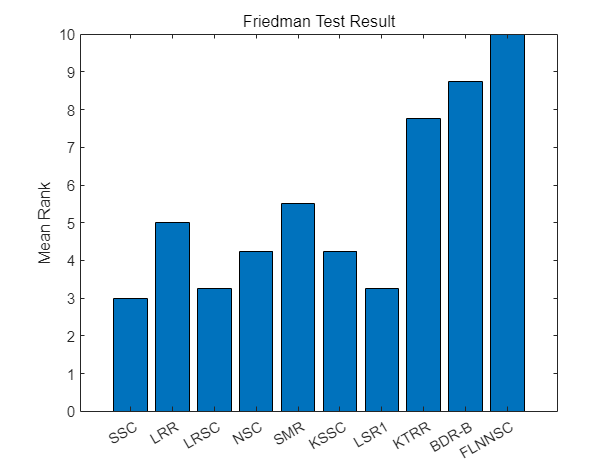


% 组的名称
groupNames = {'SSC', 'LRR', 'LRSC', 'NSC', 'SMR', 'KSSC', 'LSR1', 'KTRR', 'BDR-B', 'FLNNSC'};

% 获取组的平均排名
meanRanks = stats.meanranks;

% 生成结果图
figure;
bar(meanRanks);
set(gca, 'XTickLabel', groupNames);
ylabel('Mean Rank');
title('Friedman Test Result');